# Tutorial 8: Workspace Analysis (Part 1)

This tutorial will show how workspace analysis can be run in CASPR for cable-driven robots. This tutorial will use the ideas from the following previous tutorials:

- `T1_load_robot.mlx`

Part 1 of this tutorial will focus on using the `PointWorkspaceSimulator` to compute and plot the workspace for different workspace conditions for a 2 DoF cable-driven robot.

clear;

## Setup

### Load the robot 

Load the 2 DoF robot in the manner shown in `T1_load_robot.mlx`.

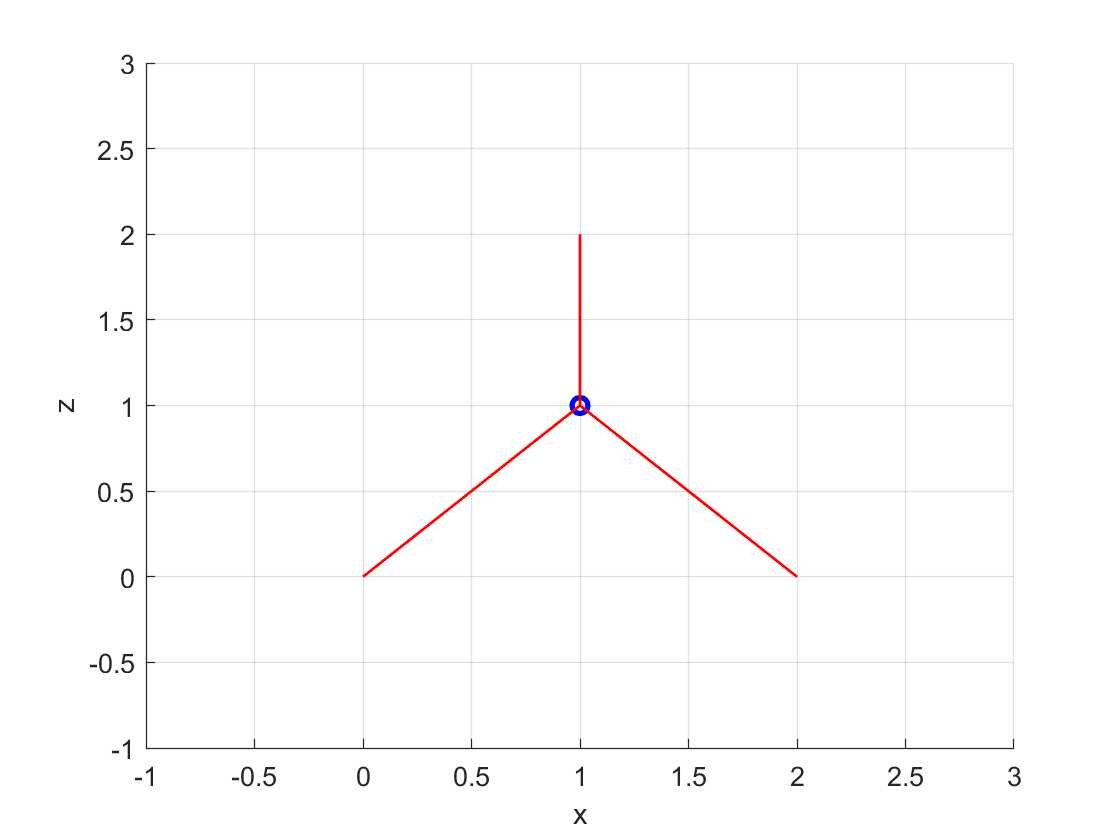

model_config = ModelConfig('Example point mass XZ');
cdpr_model = model_config.getModel('3_cables');

MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Setup the point-wise grid

A uniform (equal spacing) grid will be setup representing the set of points which the workspace analysis will be run.

% Set up the workspace simulator
% First the grid
q_min           = [0.1; -0.5];
q_max           = [1.9; 1.9];
q_step          = 0.05*ones(cdpr_model.numDofs, 1); 
uniform_grid    = UniformGrid(q_min, q_max, q_step, 'step_size');

### Setup plotting

dofs_to_plot = [1 2]; % Plot X axis as first DoF and Y axis as second DoF

For point-wise workspace, the following workspace conditions can be computed:

- Static Workspace: `WorkspaceStaticCondition`

- Wrench-Closure Workspace:` WrenchClosureCondition`

- Wrench-Feasible Workspace:` WrenchFeasibleCondition`

- Dynamic-Feasible Workspace:` DynamicFeasibleCondition`

- Cable Interference-Free Workspace:` InterferenceFreeCondition`

## 1) Static workspace analysis

The `PointWorkspaceSimulator` allows the point-wise workspace to be run. In this example, the static workspace will be first computed:

ws_condition_static = WorkspaceStaticCondition();

First, create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_static = PointWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_static}, [], []);

Next, run the simulator over the specified grid:

ws_sim_static.run();

[INFO] Workspace point 1. Completion Percentage: 0.06
[INFO] Workspace point 2. Completion Percentage: 0.11
[INFO] Workspace point 3. Completion Percentage: 0.17
[INFO] Workspace point 4. Completion Percentage: 0.22
[INFO] Workspace point 5. Completion Percentage: 0.28
[INFO] Workspace point 6. Completion Percentage: 0.33
[INFO] Workspace point 7. Completion Percentage: 0.39
[INFO] Workspace point 8. Completion Percentage: 0.44
[INFO] Workspace point 9. Completion Percentage: 0.50
[INFO] Workspace point 10. Completion Percentage: 0.55
[INFO] Workspace point 11. Completion Percentage: 0.61
[INFO] Workspace point 12. Completion Percentage: 0.66
[INFO] Workspace point 13. Completion Percentage: 0.72
[INFO] Other error : Code -8
[INFO] Workspace point 14. Completion Percentage: 0.77
[INFO] Problem infeasible
[INFO] Workspace point 15. Completion Percentage: 0.83
[INFO] Problem infeasible
[INFO] Workspace point 16. Completion Percentage: 0.88
[INFO] Problem infeasible
[INFO] Workspace point

Finally, plot the resulting 2-D workspace:

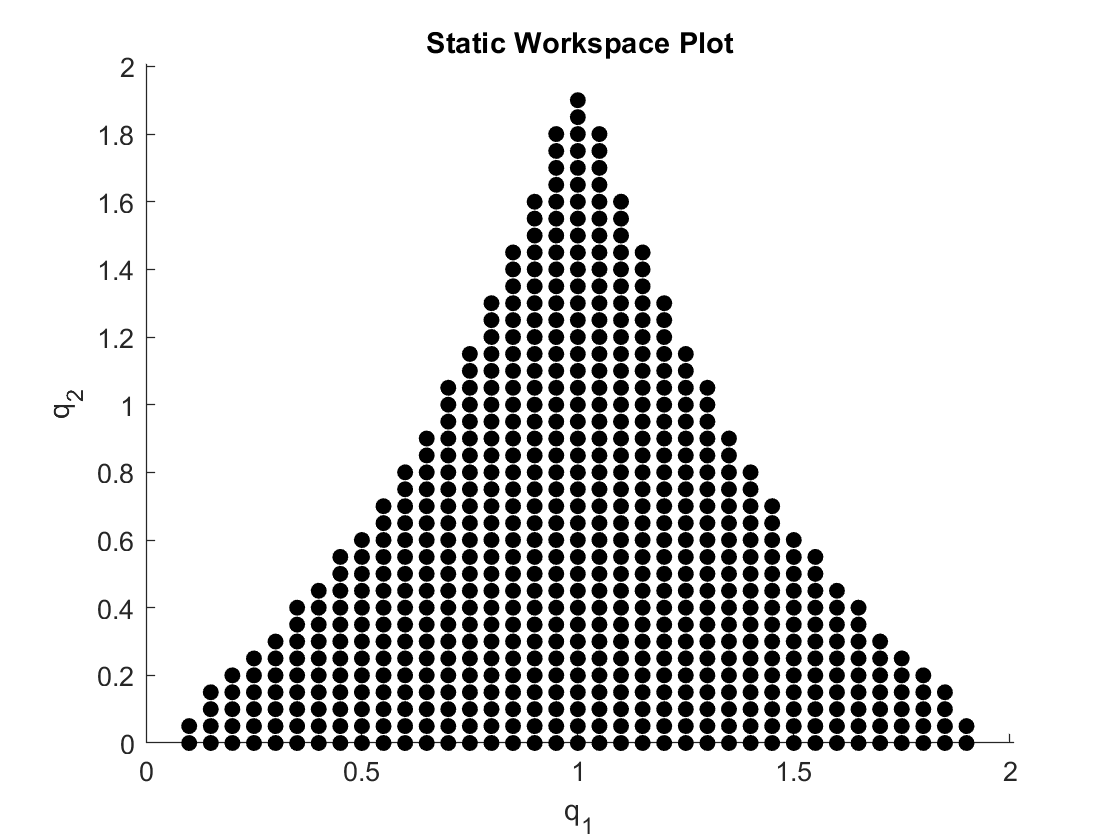

ws_sim_static.workspace.plotWorkspace(dofs_to_plot);
title('Static Workspace Plot');

## 2) Wrench-closure workspace analysis

The `PointWorkspaceSimulator` allows the point-wise workspace to be run. In this example, the static workspace will be first computed:

ws_condition_wcc = WrenchClosureCondition();

First, create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_wcw = PointWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_wcc}, [], []);

Next, run the simulator over the specified grid:

ws_sim_wcw.run();

[INFO] Workspace point 1. Completion Percentage: 0.06
[INFO] Problem infeasible
[INFO] Workspace point 2. Completion Percentage: 0.11
[INFO] Problem infeasible
[INFO] Workspace point 3. Completion Percentage: 0.17
[INFO] Problem infeasible
[INFO] Workspace point 4. Completion Percentage: 0.22
[INFO] Problem infeasible
[INFO] Workspace point 5. Completion Percentage: 0.28
[INFO] Problem infeasible
[INFO] Workspace point 6. Completion Percentage: 0.33
[INFO] Problem infeasible
[INFO] Workspace point 7. Completion Percentage: 0.39
[INFO] Problem infeasible
[INFO] Workspace point 8. Completion Percentage: 0.44
[INFO] Problem infeasible
[INFO] Workspace point 9. Completion Percentage: 0.50
[INFO] Problem infeasible
[INFO] Workspace point 10. Completion Percentage: 0.55
[INFO] Problem infeasible
[INFO] Workspace point 11. Completion Percentage: 0.61
[INFO] Problem infeasible
[INFO] Workspace point 12. Completion Percentage: 0.66
[INFO] Workspace point 13. Completion Percentage: 0.72
[INFO] W

Finally, plot the resulting 2-D workspace:

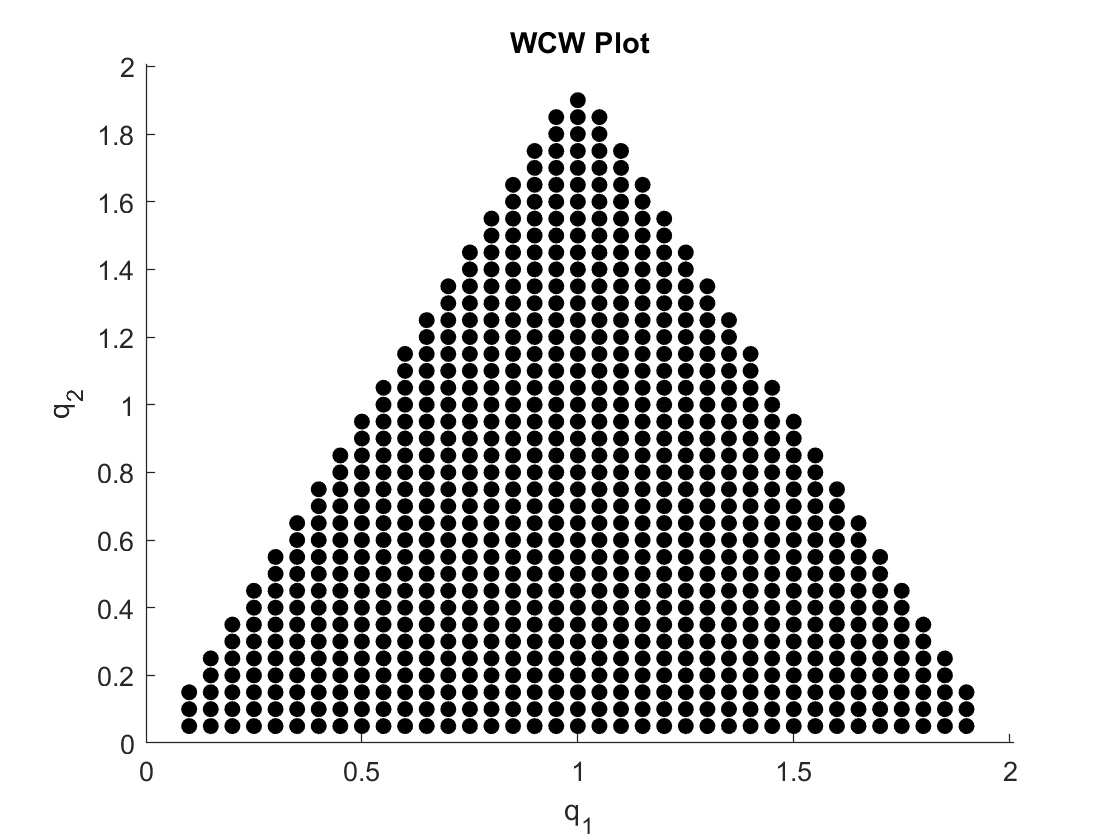

ws_sim_wcw.workspace.plotWorkspace(dofs_to_plot);
title('WCW Plot');

## 3) Wrench-feasible workspace analysis

The `PointWorkspaceSimulator` allows the point-wise workspace to be run. In this example, the static workspace will be first computed:

desired_wrench_set = [0; cdpr_model.bodyModel.bodies{1}.m*9.81] + 20*[-1 -1 1 1; -1 1 -1 1];
ws_condition_wfc = WrenchFeasibleCondition(desired_wrench_set);

First, create the simulator object using the robot model, grid and workspace condition(s):

ws_sim_wfw = PointWorkspaceSimulator(cdpr_model, uniform_grid, {ws_condition_wfc}, [], []);

Next, run the simulator over the specified grid:

ws_sim_wfw.run();

[INFO] Workspace point 1. Completion Percentage: 0.06
[INFO] Workspace point 2. Completion Percentage: 0.11
[INFO] Workspace point 3. Completion Percentage: 0.17
[INFO] Workspace point 4. Completion Percentage: 0.22
[INFO] Workspace point 5. Completion Percentage: 0.28
[INFO] Workspace point 6. Completion Percentage: 0.33
[INFO] Workspace point 7. Completion Percentage: 0.39
[INFO] Workspace point 8. Completion Percentage: 0.44
[INFO] Workspace point 9. Completion Percentage: 0.50
[INFO] Workspace point 10. Completion Percentage: 0.55
[INFO] Workspace point 11. Completion Percentage: 0.61
[INFO] Workspace point 12. Completion Percentage: 0.66
[INFO] Workspace point 13. Completion Percentage: 0.72
[INFO] Workspace point 14. Completion Percentage: 0.77
[INFO] Workspace point 15. Completion Percentage: 0.83
[INFO] Workspace point 16. Completion Percentage: 0.88
[INFO] Workspace point 17. Completion Percentage: 0.94
[INFO] Workspace point 18. Completion Percentage: 0.99
[INFO] Workspace po

Finally, plot the resulting 2-D workspace:

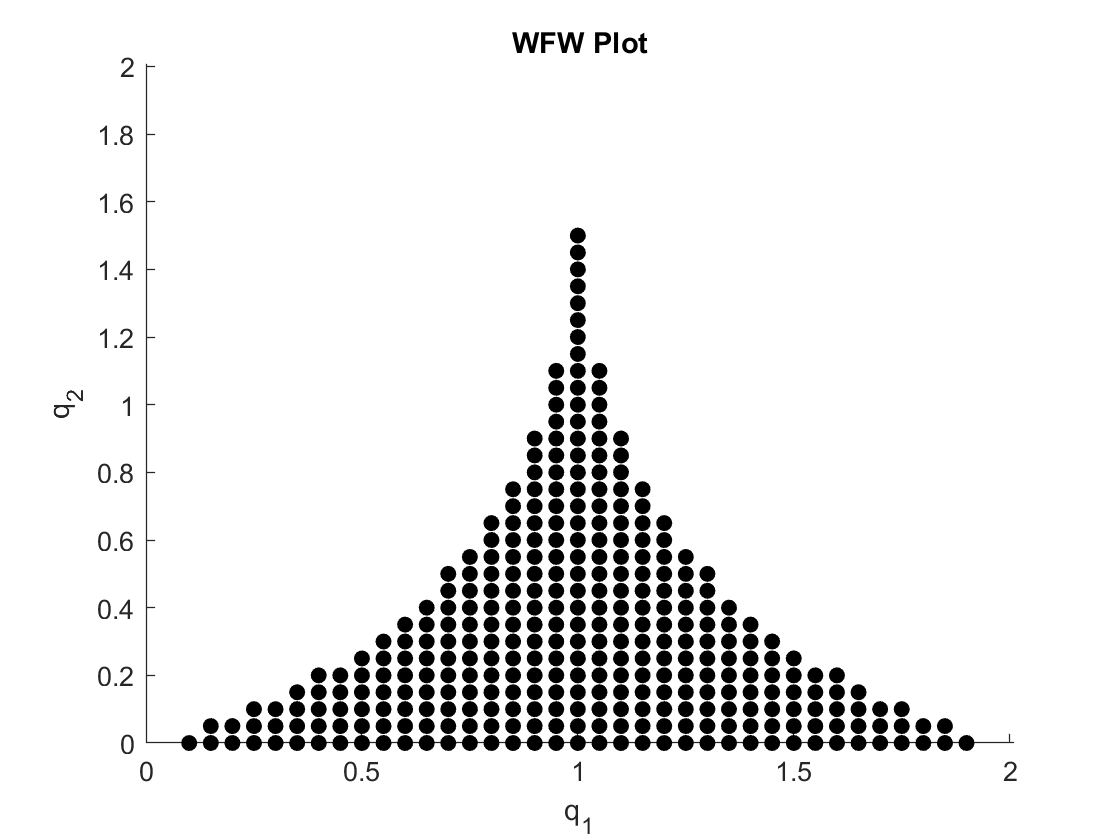

ws_sim_wfw.workspace.plotWorkspace(dofs_to_plot);
title('WFW Plot');

## Multiple workspace conditions

In addition to single conditions in the above examples, it is possible to generate the workspace for multiple workspace conditions simultaneously, by simply providing multiple conditions:

ws_conditions = {ws_condition_static, ws_condition_wcc, ws_condition_wfc};
ws_sim_multiple = PointWorkspaceSimulator(cdpr_model, uniform_grid, ws_conditions, [], []);
ws_sim_multiple.run();

[INFO] Workspace point 1. Completion Percentage: 0.06
[INFO] Problem infeasible
[INFO] Workspace point 2. Completion Percentage: 0.11
[INFO] Problem infeasible
[INFO] Workspace point 3. Completion Percentage: 0.17
[INFO] Problem infeasible
[INFO] Workspace point 4. Completion Percentage: 0.22
[INFO] Problem infeasible
[INFO] Workspace point 5. Completion Percentage: 0.28
[INFO] Problem infeasible
[INFO] Workspace point 6. Completion Percentage: 0.33
[INFO] Problem infeasible
[INFO] Workspace point 7. Completion Percentage: 0.39
[INFO] Problem infeasible
[INFO] Workspace point 8. Completion Percentage: 0.44
[INFO] Problem infeasible
[INFO] Workspace point 9. Completion Percentage: 0.50
[INFO] Problem infeasible
[INFO] Workspace point 10. Completion Percentage: 0.55
[INFO] Problem infeasible
[INFO] Workspace point 11. Completion Percentage: 0.61
[INFO] Problem infeasible
[INFO] Workspace point 12. Completion Percentage: 0.66
[INFO] Workspace point 13. Completion Percentage: 0.72
[INFO] O

After running the analysis for all of the conditions, you can choose to plot the intersection of all conditions:

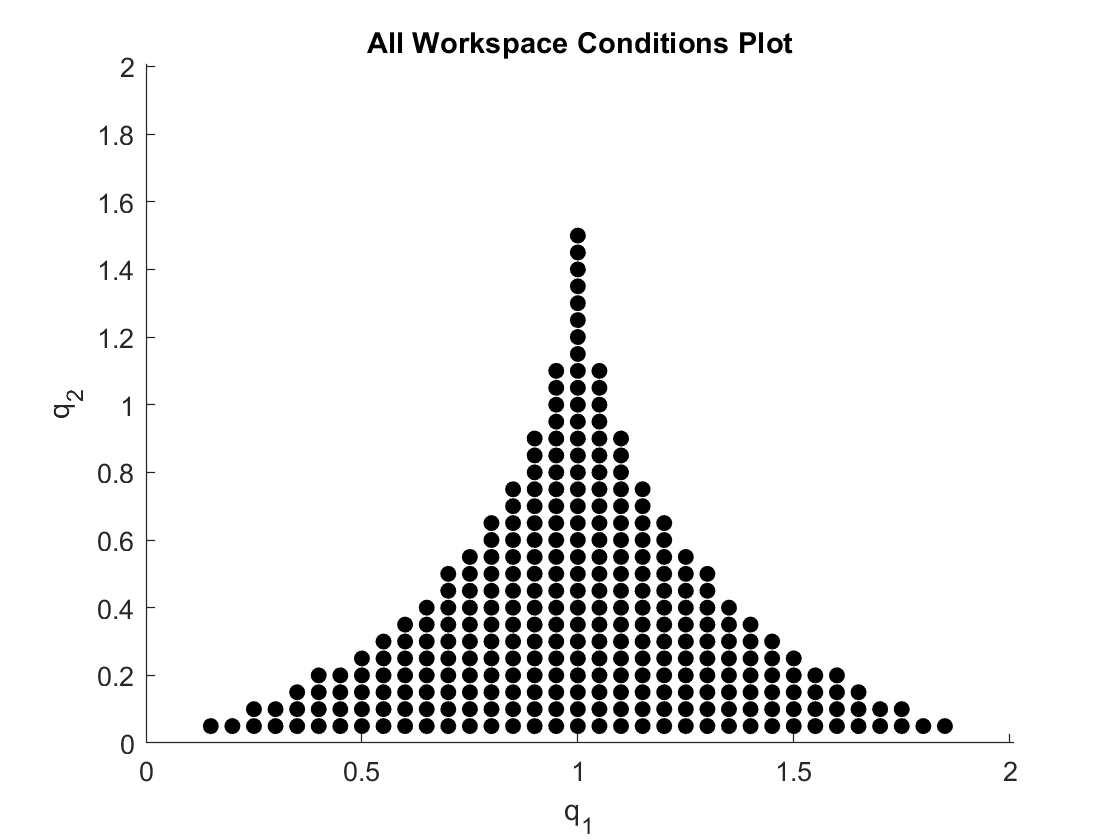

ws_sim_multiple.workspace.plotWorkspace(dofs_to_plot);
title('All Workspace Conditions Plot');

Or plot one or more of the conditions, for example just the `ws_condition_wcc `(index number 2 from `ws_conditions`):

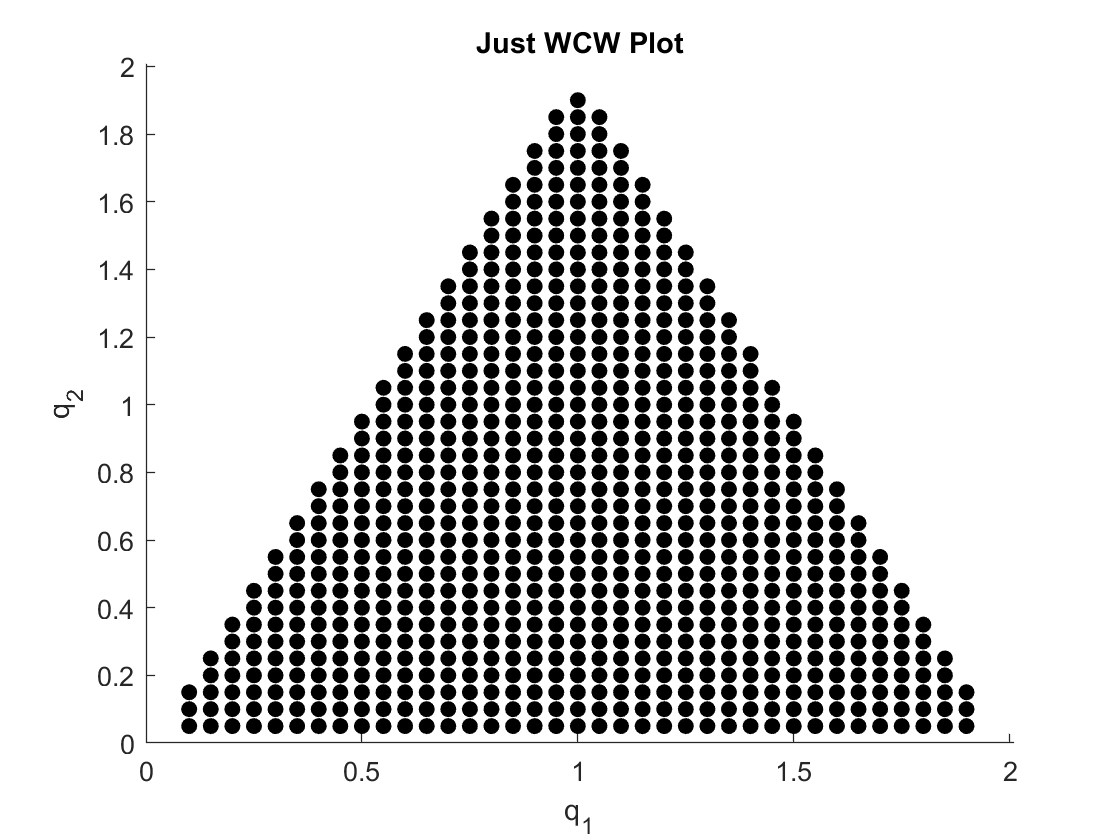

ws_sim_multiple.workspace.plotWorkspace(dofs_to_plot, [2]);
title('Just WCW Plot');

Or the intersection of `ws_condition_wcc` and `ws_condition_wfc` (indices number 2 and 3 from `ws_conditions`):

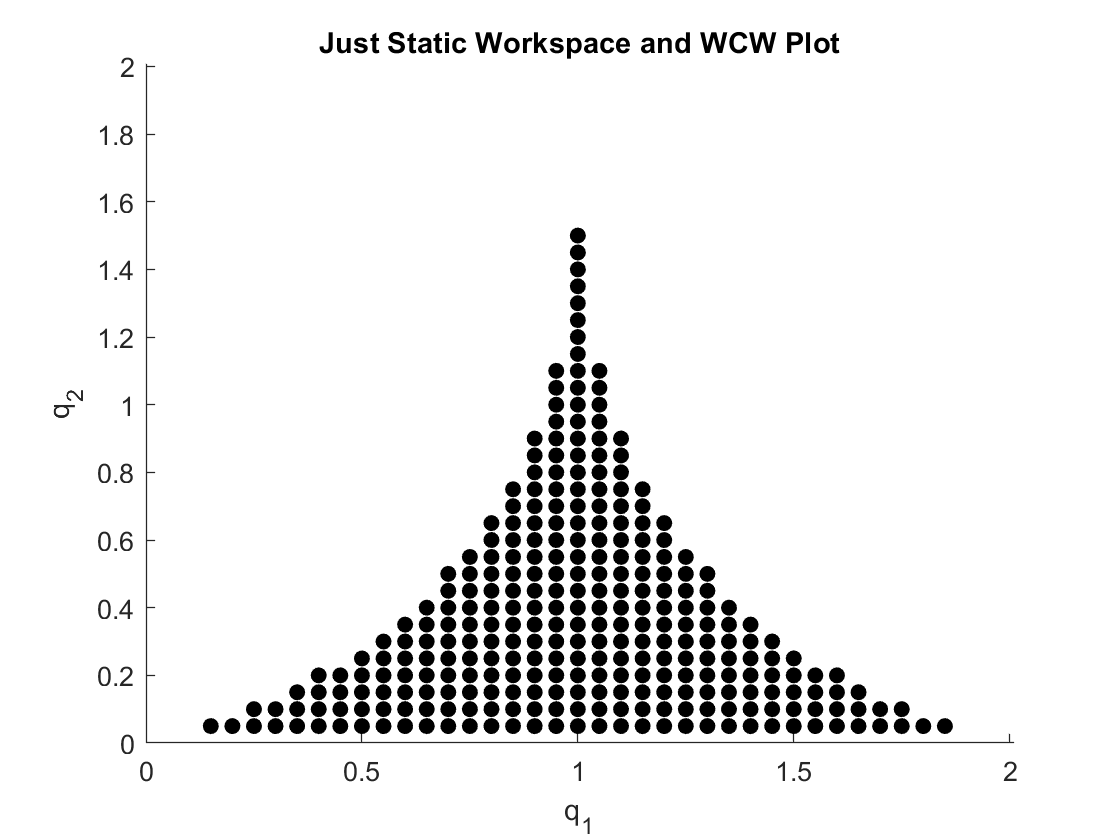

ws_sim_multiple.workspace.plotWorkspace(dofs_to_plot, [2 3]);
title('Just Static Workspace and WCW Plot');